addpath('\\badwwmi-k04-qtm\\Data_QTM\_data\run19\MeasurementProtocolHT')

## Templates

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B mT)

% clear % plot raw transmission
% vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
% load('', vari{:})
% table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% % select power-range
% powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);
% 
% figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% 
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end
% 
% ylabel('|S_{21}| (dB)','FontSize',font_size)
% xlabel('Frequency (GHz)','FontSize',font_size)
% legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B mT)

% clear % plot raw S21 and normalized S21, phase and delay
% vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
% load('', vari{:})
% table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% % select power-range
% powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);
% 
% % normalize to highest selected power
% zz_norm = zz(:,ind_low:ind_high) - zz(:,ind_high);
% zzph_norm = zzph(:,ind_low:ind_high) - zzph(:,ind_high);
% zzed_norm = zzed(:,ind_low:ind_high) - zzed(:,ind_high);
% 
% % subplot properties
% n_sub = 4; % number of subplots
% margin_l = 0.1; margin_r = 0.05; height_sub = 0.225; delta_sub = 0.01;
% font_size = 12;
% 
% figure
% for i = 1:n_sub
%     axes(i) = subplot('Position', [margin_l 1-i*height_sub-i*delta_sub 1-margin_l-margin_r height_sub]);
% end
% hold(axes, 'on')
% cc = turbo(length(powers));
% 
% for i = 1:length(powers)
%     plot(axes(1), yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
%     plot(axes(2), yy/1e9, zz_norm(:,i), 'Color', cc(i,:)) % normalized S21
%     plot(axes(3), yy/1e9, zzph_norm(:,i), 'Color', cc(i,:)) % normalized phase
%     plot(axes(4), yy/1e9, zzed_norm(:,i), 'Color', cc(i,:)) % normalized group delay
% end
% 
% ylabel(axes(1), '|S_{21}| (dB)','FontSize',font_size)
% ylabel(axes(2), 'Norm. |S_{21}| (dB)','FontSize',font_size)
% ylabel(axes(3), 'Norm. phase (deg)','FontSize',font_size)
% ylabel(axes(4), 'Norm. group delay','FontSize',font_size)
% xlabel(axes(4), 'Frequency (GHz)','FontSize',font_size)
% legend(axes(1), 'Location', 'northoutside', 'NumColumns', length(powers))
% set(axes(1:end-1), 'xTickLabel', '')
% linkaxes(axes, 'x');

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, B - B mT, pow dBm)

% clear % plot field sweep
% vari = {"vna_pow" "B_step" "vna_res" "vna_ifbw" "vna_aver" "sam" "yy" "B_field" "zz" "zzph" "zzed"};
% load('', vari{:})
% table({strcat(num2str(vna_pow), ' dBm')},{strcat(num2str(B_step),' mT')},{num2str(vna_res)}, ...
%     {strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)}, ...
%     'VariableNames',{'Power','Step','Points','Bandwidth','Averages'})
% [yy, B_field, zz, zzph, zzed] = crop_data( ...
%     yy, B_field, zz, zzph, zzed, yy(1), yy(end), B_field(1), B_field(end));

Transmission normalized

% zz_norm = normalize_freq_field_mean(zz);
% % zz_norm = normalize_zero_field(zz);
% figure; plot_surface(yy/1e9, B_field, zz_norm, [-1 1.5]*0.2, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Normalize with composite background (smoothed)

% % load background spectrum
% load('\\badwwmi-021-res\DATA_wmi\_data\run34\Georg\MeasurementProtocol\Broadband_ESR\composite_background_-24dBm_r34.mat')
% % interpolate spectrum and normalize data
% bg_comp_interp = interp1(yy_composite, smoothdata(bg_composite, 'movmean', 5), yy);
% zz_norm_comp = zz - bg_comp_interp';
% figure; plot_surface(yy/1e9, B_field, zz_norm_comp, [-1 1]*0.5, ...
%         {'f (GHz)' 'B (mT)' 'Norm. |S_{21}| (dB)'});

Phase normalized

% zzph_norm = normalize_freq_field_mean(zzph);
% figure; plot_surface(yy/1e9, B_field, zzph_norm, [-1 1]*3, ...
%         {'f (GHz)' 'B (mT)' 'Norm. phase (deg)'});

Delay normalized

% zzed_norm = normalize_freq_field_mean(zzed);
% figure; plot_surface(yy/1e9, B_field, zzed_norm, [-1 1]*5e-8, ...
%         {'f (GHz)' 'B (mT)' 'Norm. delay (s)'});

## Power sweeps

#### 25-01-dd @ hh:mm:ss, comment (F.r - e.q GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_100_4000MHz_7mK_Broadband_06-Mar-2025_@_15-05-52\power_sweep_r19s1_2_nat_Er_CWO_100_4000MHz_7mK_Broadband@_15-05-52.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-43--43 dBm'}    {'7801'}    {'100 Hz'}     {'1'}        {'7mK'}  


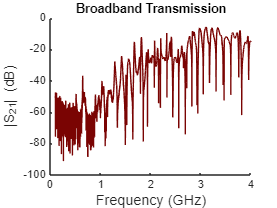

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

title("Broadband Transmission")
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 15:35:29, Broadband (3.022-3.034 - e.q GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3022_3034MHz_7mK_Broadband_06-Mar-2025_@_15-41-01\power_sweep_r19s1_2_nat_Er_CWO_3022_3034MHz_7mK_Broadband@_15-41-01.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 15:35:29, Broadband (3.022-3.034 - e.q GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3022_3034MHz_7mK_Broadband_06-Mar-2025_@_15-35-29\power_sweep_r19s1_2_nat_Er_CWO_3022_3034MHz_7mK_Broadband@_15-35-29.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 15:49:36, Broadband (2.7-2.71 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2700_2710MHz_7mK_Broadband_06-Mar-2025_@_15-49-36\power_sweep_r19s1_2_nat_Er_CWO_2700_2710MHz_7mK_Broadband@_15-49-36.mat')

table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-43--43 dBm'}    {'2501'}    {'100 Hz'}     {'1'}        {'7mK'}  


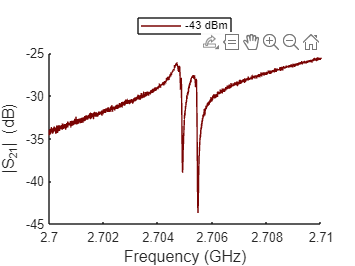

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 15:54:36, Broadband (2.649-2.659 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2649_2659MHz_7mK_Broadband_06-Mar-2025_@_15-54-36\power_sweep_r19s1_2_nat_Er_CWO_2649_2659MHz_7mK_Broadband@_15-54-36.mat')

table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-43--43 dBm'}    {'2501'}    {'100 Hz'}     {'1'}        {'7mK'}  


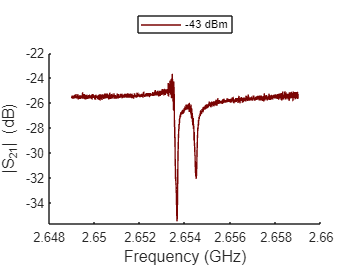

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
xlim([2.648 2.66])
ylim([-35.7 -22.0])
legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 16:02:05, Broadband (2.327-2.337 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2327_2337MHz_7mK_Broadband_06-Mar-2025_@_16-02-05\power_sweep_r19s1_2_nat_Er_CWO_2327_2337MHz_7mK_Broadband@_16-02-05.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 16:05:36, Broadband (1.43-1.44 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_1431_1441MHz_7mK_Broadband_06-Mar-2025_@_16-05-36\power_sweep_r19s1_2_nat_Er_CWO_1431_1441MHz_7mK_Broadband@_16-05-36.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 16:15:32, Broadband (0.892-0.902 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_892_902MHz_7mK_Broadband_06-Mar-2025_@_16-15-32\power_sweep_r19s1_2_nat_Er_CWO_892_902MHz_7mK_Broadband@_16-15-32.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-06 @ 16:19:52, Broadband (0.317-0.327 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_317_327MHz_7mK_Broadband_06-Mar-2025_@_16-19-52\power_sweep_r19s1_2_nat_Er_CWO_317_327MHz_7mK_Broadband@_16-19-52.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:30:04, Broadband (0.368-0.378 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_368_378MHz_7mK_Broadband_07-Mar-2025_@_10-30-04\power_sweep_r19s1_2_nat_Er_CWO_368_378MHz_7mK_Broadband@_10-30-04.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:30:04, Broadband (0.368-0.378 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_368_378MHz_7mK_Broadband_07-Mar-2025_@_10-30-04\power_sweep_r19s1_2_nat_Er_CWO_368_378MHz_7mK_Broadband@_10-30-04.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:35:54, Broadband (3.02-3.034 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3020_3034MHz_7mK_Broadband_07-Mar-2025_@_10-35-54\power_sweep_r19s1_2_nat_Er_CWO_3020_3034MHz_7mK_Broadband@_10-35-54.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))


#### 25-03-07 @ 10:42:19, Broadband (3.475-3.495 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3475_3495MHz_7mK_Broadband_07-Mar-2025_@_10-42-19\power_sweep_r19s1_2_nat_Er_CWO_3475_3495MHz_7mK_Broadband@_10-42-19.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:47:21, Broadband (3.41-3.47 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3410_3470MHz_7mK_Broadband_07-Mar-2025_@_10-47-21\power_sweep_r19s1_2_nat_Er_CWO_3410_3470MHz_7mK_Broadband@_10-47-21.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:51:27, Broadband (3.36-3.4 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3360_3400MHz_7mK_Broadband_07-Mar-2025_@_10-51-27\power_sweep_r19s1_2_nat_Er_CWO_3360_3400MHz_7mK_Broadband@_10-51-27.mat')
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 10:56:57, Broadband (3.16-3.24 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_3160_3240MHz_7mK_Broadband_07-Mar-2025_@_10-56-57\power_sweep_r19s1_2_nat_Er_CWO_3160_3240MHz_7mK_Broadband@_10-56-57.mat')

table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-43--43 dBm'}    {'6001'}    {'100 Hz'}     {'1'}        {'7mK'}  


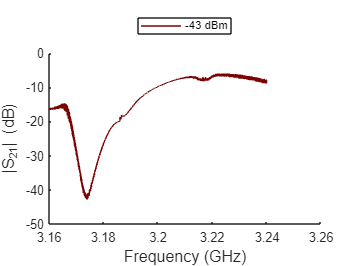

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 11:01:03, Broadband (2.695-2.715 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2695_2715MHz_7mK_Broadband_07-Mar-2025_@_11-01-03\power_sweep_r19s1_2_nat_Er_CWO_2695_2715MHz_7mK_Broadband@_11-01-03.mat')

table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-43--43 dBm'}    {'6001'}    {'100 Hz'}     {'1'}        {'7mK'}  


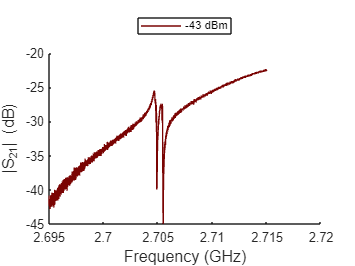

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-07 @ 11:35:34, Constant Power (-43dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702_2708MHz_7mK_power_testing_with_pause_07-Mar-2025_@_11-35-34\power_sweep_r19s1_2_nat_Er_CWO_2702_2708MHz_7mK_power_testing_with_pause@_11-35-34.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
% legend([num2str(powers) ' dBm'])

#### 25-03-07 @ 12:18:37, Constant Power (-42dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_07-Mar-2025_@_12-18-37\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause@_12-18-37.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-42--42 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


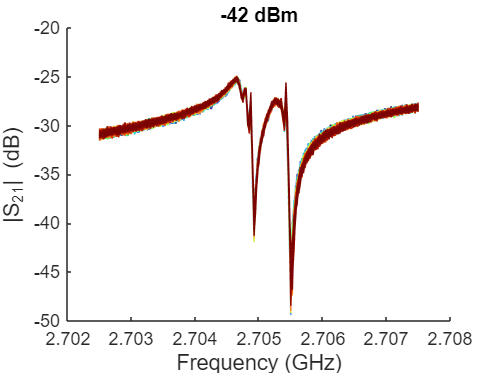

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend([num2str(powers) ' dBm'])

#### 25-03-07 @ 13:00:14, Constant Power (-38dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_07-Mar-2025_@_13-00-14\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause@_13-00-14.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
% legend([num2str(powers) ' dBm'])

#### 25-03-07 @ 13:43:02, Constant Power (-34dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_07-Mar-2025_@_13-43-02\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause@_13-43-02.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
% legend([num2str(powers) ' dBm'])

#### 25-03-07 @ 14:21:59, Constant Power (-30dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_07-Mar-2025_@_14-21-59\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause@_14-21-59.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
grid on
% legend([num2str(powers) ' dBm'])

#### 25-03-07 @ 15:03:04, Constant Power (-20dB) with 1s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_07-Mar-2025_@_15-03-04\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause@_15-03-04.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)
% legend([num2str(powers) ' dBm'])

#### 25-03-12 @ 17:00, Constant Power (-41dB) with 1.5s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-41dB_12-Mar-2025_@_16-06-23\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-41dB@_16-06-23.mat", vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-41--41 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


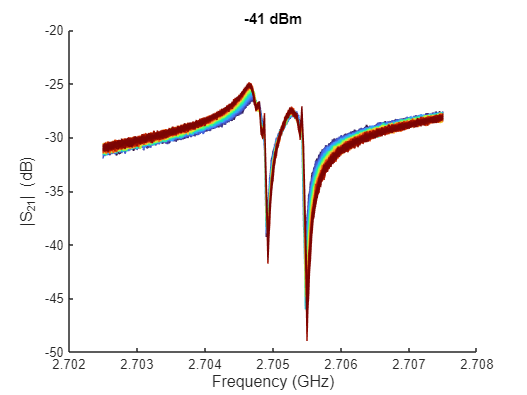

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend([num2str(powers) ' dBm'])

#### 25-03-12 @ 17:44, Constant Power (-40dB) with 1.5s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-40dB_12-Mar-2025_@_17-00-47\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-40dB@_17-00-47.mat', vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-40--40 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


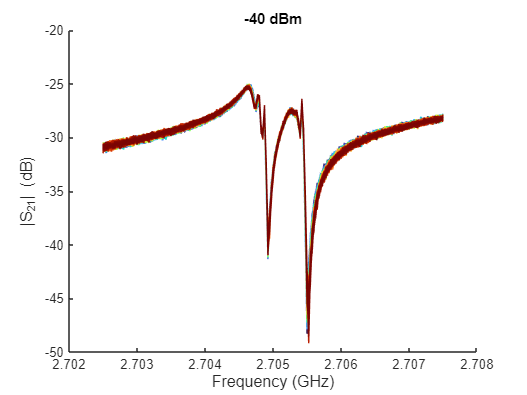

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend([num2str(powers) ' dBm'])

#### 25-03-12 @ 17:00, Constant Power (-39dB) with 1.5s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-39dB_12-Mar-2025_@_17-54-42\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-39dB@_17-54-42.mat", vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-39--39 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


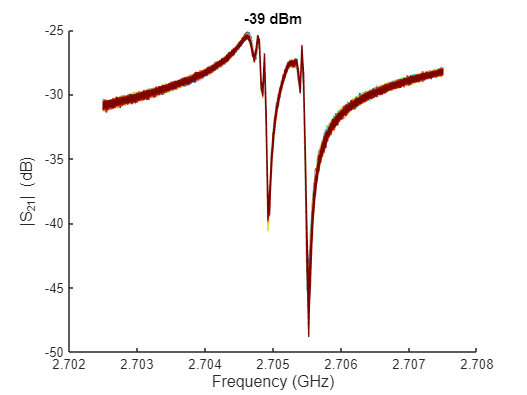

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend([num2str(powers) ' dBm'])

#### 25-03-13 @ 10:23, Constant Power (-41dB) with 1.5s pause (2.7025 -2.7075 GHz, PS off)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-41dB_13-Mar-2025_@_10-23-56\power_sweep_r19s1_2_nat_Er_CWO_2702.5_2707.5MHz_7mK_power_testing_with_pause_-41dB@_10-23-56.mat", vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-41--41 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


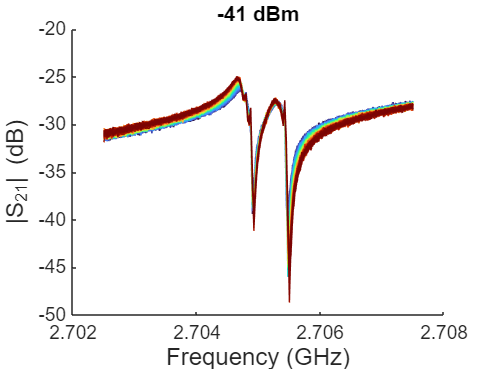

% select power-range
powers = xx(1):P_step:xx(end);
% ind_low = find(xx==powers(1));
% ind_high = find(xx==powers(end));
% zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
% cc = turbo(length(powers));
% for i = 1:length(powers)
%     plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
% end

% script modified for constant power (Hayden)

cc = turbo(size(xx,2));
for i = 1:size(xx,2) 
    plot(yy/1e9, zz(:,i), 'Color',cc(i,:),'DisplayName', [num2str(powers) ' dBm'])
end

title([num2str(vna_pow) ' dBm'])
ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

% legend([num2str(powers) ' dBm'])

#### 25-03-13 @ 11:54:39, Power sweep -60 to -10dB (2.685 - 2.725 GHz, B mT)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_natEr_CWO_2685_2725MHz_7mK_1.9353GHz_13-Mar-2025_@_11-54-39\power_sweep_r19s1_2_natEr_CWO_2685_2725MHz_7mK_1.9353GHz@_11-54-39_dia.mat", vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range         Points     Bandwidth     Averages    Temperature
    _______________    _______    __________    ________    ___________

    {'-60--10 dBm'}    {'801'}    {'100 Hz'}     {'1'}        {'7mK'}  


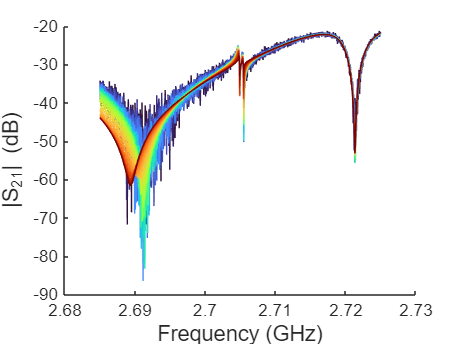

% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 12;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

%legend('Location', 'northoutside', 'NumColumns', length(powers)) 

#### 25-03-13 @ 11:54:39, Power sweep -60 to -10dB (2.685 - 2.725 GHz, B mT)

clear % plot raw transmission
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\power_sweep_r19s1_2_nat_Er_CWO_2690_2720MHz_7mK_1.9353GHz_13-Mar-2025_@_12-34-23\power_sweep_r19s1_2_nat_Er_CWO_2690_2720MHz_7mK_1.9353GHz@_12-34-23.mat", vari{:})
table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
         Range          Points     Bandwidth     Averages    Temperature
    _______________    ________    __________    ________    ___________

    {'-60--10 dBm'}    {'1201'}    {'100 Hz'}     {'1'}        {'7mK'}  


% select power-range
powers = xx(1):P_step:xx(end);
ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

figure; hold on; font_size = 13;
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
end

colormap(cc)
caxis([-60 -10])
cb = colorbar;
cb.Label.String = 'VNA Power (dB)'

cb =   ColorBar (VNA Power (dB)) with properties:

    Location: 'eastoutside'
      Limits: [-60 -10]
    FontSize: 9
    Position: [0.8327 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


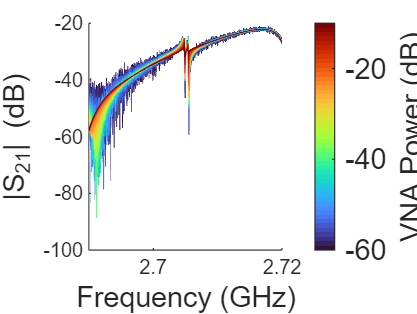

cb.Label.FontSize = 16;       % Change label font size
cb.FontSize = 13; 

ylabel('|S_{21}| (dB)','FontSize',font_size)
xlabel('Frequency (GHz)','FontSize',font_size)

%legend('Location', 'northoutside', 'NumColumns', length(powers))

#### 25-03-13 @ hh:mm:ss, Decay Measurement (2.7025 - 2.7075 GHz, B mT)

clear % plot raw S21 and normalized S21, phase and delay
vari = {"vna_pow" "vna_res" "vna_ifbw" "vna_aver" "P_step" "xx" "yy" "zz" "zzph" "zzed" "temp"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2705_MHz_-10dBm_7mK__13-Mar-2025_@_13-52-08\mw_time_spectrum_r19s2_nat_Er_CWO_2705_MHz_-10dBm_7mK__@13-52-08.mat", vari{:})

table({strcat(num2str(xx(1)), '-', num2str(xx(end)), ' dBm')},{num2str(vna_res)},{strcat(num2str(vna_ifbw), ' Hz')},{num2str(vna_aver)},{temp},'VariableNames',{'Range', 'Points', 'Bandwidth','Averages','Temperature'})

ans = 1×5 table
              Range              Points     Bandwidth     Averages    Temperature
    _________________________    _______    __________    ________    ___________

    {'27.4562-5127.3951 dBm'}    {'201'}    {'200 Hz'}     {'1'}        {'7mK'}  


% select power-range
powers = xx(1):P_step:xx(end);

Unrecognized function or variable 'P_step'.

ind_low = find(xx==powers(1));
ind_high = find(xx==powers(end));
zz_sel = zz(:,ind_low:ind_high);

% normalize to highest selected power
zz_norm = zz(:,ind_low:ind_high) - zz(:,ind_high);
zzph_norm = zzph(:,ind_low:ind_high) - zzph(:,ind_high);
zzed_norm = zzed(:,ind_low:ind_high) - zzed(:,ind_high);

% subplot properties
n_sub = 4; % number of subplots
margin_l = 0.1; margin_r = 0.05; height_sub = 0.225; delta_sub = 0.01;
font_size = 12;

figure
for i = 1:n_sub
    axes(i) = subplot('Position', [margin_l 1-i*height_sub-i*delta_sub 1-margin_l-margin_r height_sub]);
end
hold(axes, 'on')
cc = turbo(length(powers));

for i = 1:length(powers)
    plot(axes(1), yy/1e9, zz_sel(:,i), 'Color', cc(i,:), 'DisplayName', [num2str(powers(i)) ' dBm']) % raw S21
    plot(axes(2), yy/1e9, zz_norm(:,i), 'Color', cc(i,:)) % normalized S21
    plot(axes(3), yy/1e9, zzph_norm(:,i), 'Color', cc(i,:)) % normalized phase
    plot(axes(4), yy/1e9, zzed_norm(:,i), 'Color', cc(i,:)) % normalized group delay
end

ylabel(axes(1), '|S_{21}| (dB)','FontSize',font_size)
ylabel(axes(2), 'Norm. |S_{21}| (dB)','FontSize',font_size)
ylabel(axes(3), 'Norm. phase (deg)','FontSize',font_size)
ylabel(axes(4), 'Norm. group delay','FontSize',font_size)
xlabel(axes(4), 'Frequency (GHz)','FontSize',font_size)
legend(axes(1), 'Location', 'northoutside', 'NumColumns', length(powers))
set(axes(1:end-1), 'xTickLabel', '')
linkaxes(axes, 'x');